# LQG (Linearized System)

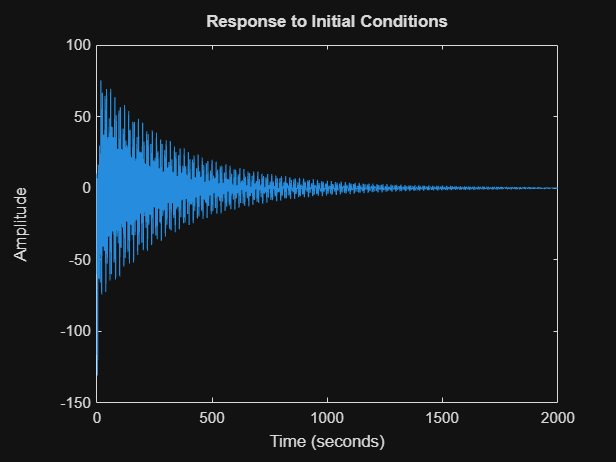

M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.81;

A=[0 1 0 0 0 0;
   0 0 -(m1*g)/M 0 -(m2*g)/M 0;
   0 0 0 1 0 0;
   0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
   0 0 0 0 0 1;
   0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];

R = 0.1;

% From the previous case, we have determined that only C1, C3 and C4 were
% observable. Hence, we are going to consider only these 3 cases.

C1 = [1 0 0 0 0 0];  % x(t)
C3 = [1 0 0 0 0 0; 0 0 0 0 1 0]; % x(t) and theta2(t)
C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; % x(t), theta1(t) & theta2(t)

D = 0; 
% Initial Conditions for the Luenberger observer - 12 state variables out of which 
% 6 are actual and the other 6 are estimates
x0 = [10;0;20;0;60;0;0;0;0;0;0;0];
% The order for state variables = [x,dx,theta1,dtheta1,theta2,dtheta2]
% The estimates are also taken in the same order

% Calling LQR function to obtain the K matrix
K = lqr(A,B,Q,R);
vd = 0.3*eye(6); % process noise
vn = 1; % measurement noise

K_pop1 = lqr(A',C1',vd,vn)'; % Gain matrix of Kalman filter for C1
K_pop3 = lqr(A',C3',vd,vn)'; % Gain matrix of Kalman filter for C3
K_pop4 = lqr(A',C4',vd,vn)'; % Gain matrix of Kalman filter for C4

% Observing the State Space corresponding to the C1 observable system
sys1 = ss([(A-B*K) B*K; zeros(size(A)) (A-K_pop1*C1)], [B;zeros(size(B))],[C1 zeros(size(C1))], D);
figure
initial(sys1,x0)

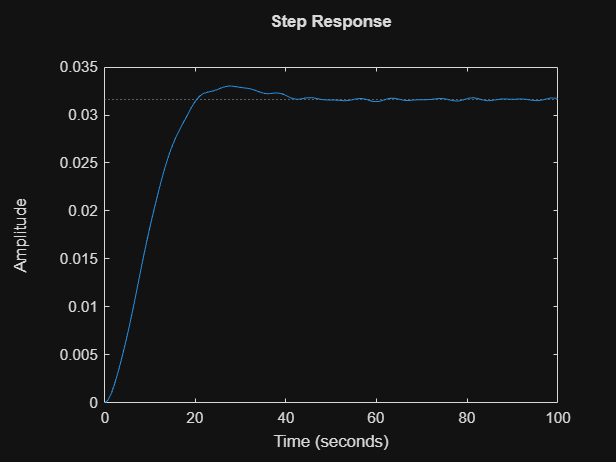

figure
step(sys1)

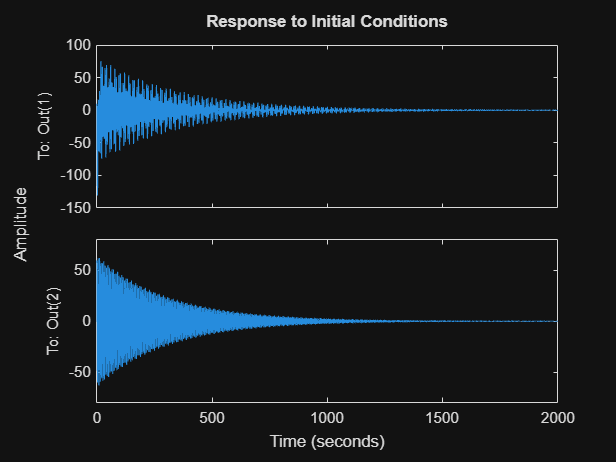

% Observing the State Space corresponding to the C3 observable system 
sys3 = ss([(A-B*K) B*K; zeros(size(A)) (A-K_pop3*C3)], [B;zeros(size(B))],[C3 zeros(size(C3))], D);
figure
initial(sys3,x0)

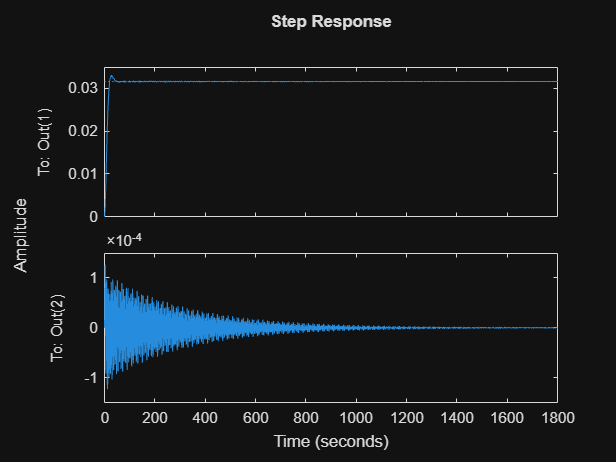

figure
step(sys3)

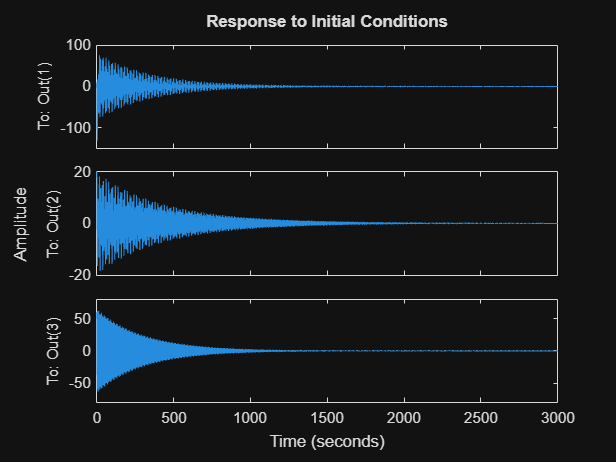

% Observing the State Space corresponding to the C4 observable system
sys4 = ss([(A-B*K) B*K; zeros(size(A)) (A-K_pop4*C4)], [B;zeros(size(B))],[C4 zeros(size(C4))], D);
figure
initial(sys4,x0)

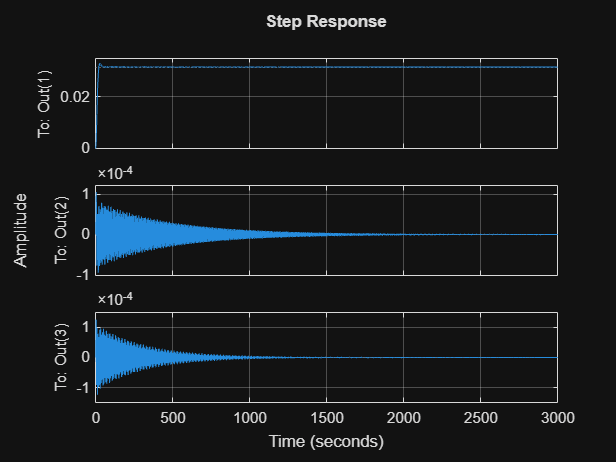

figure
step(sys4)

grid on